# Designing FIR filters using windows

## 3.1. Characteristics of window functions (use the fdatool)

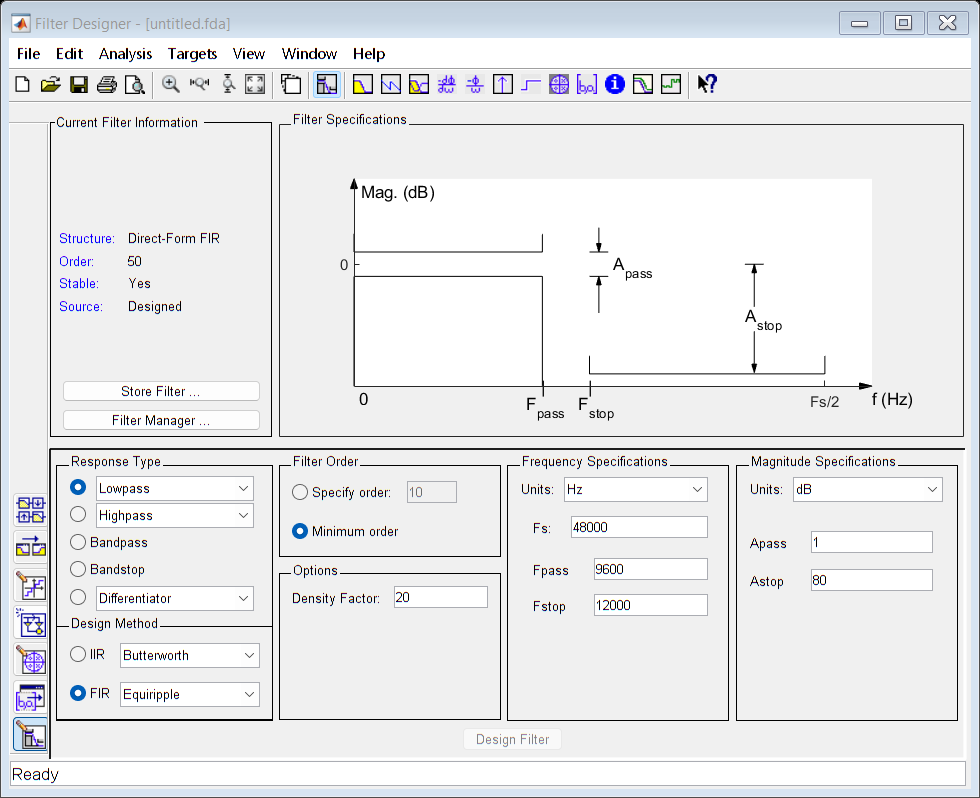

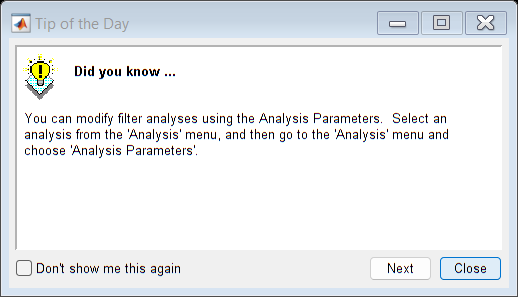

fdatool;

Initializing Window Designer....

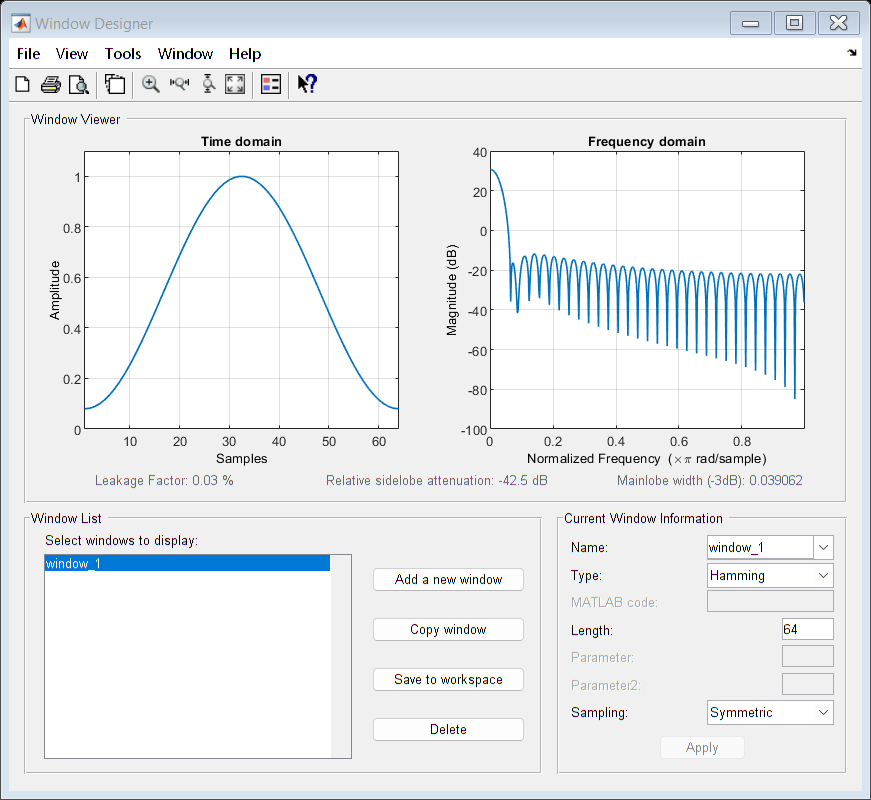

. done. 


windowDesigner;

### 3.2. FIR Filter design and application using the Kaiser window

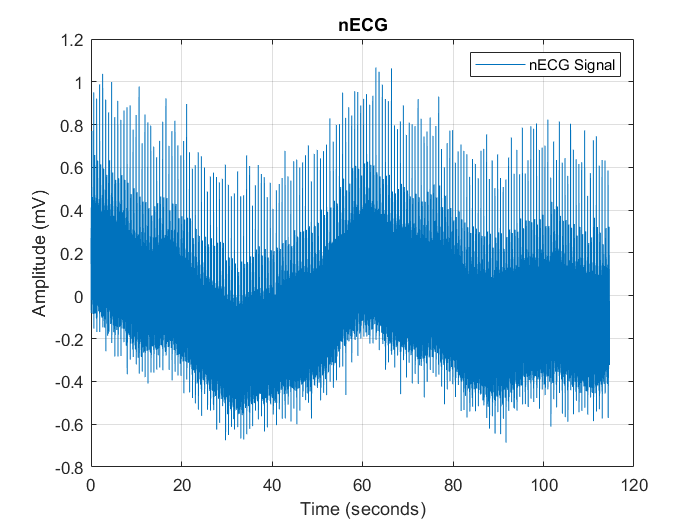

% Plotting the signal and the PSD

load("ECG_with_noise.mat");

fs = 500;
time = (0:length(nECG)-1)/fs; %time_array

figure; %plot signal
plot(time, nECG);
title('nECG');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on; 
legend('nECG Signal'); 

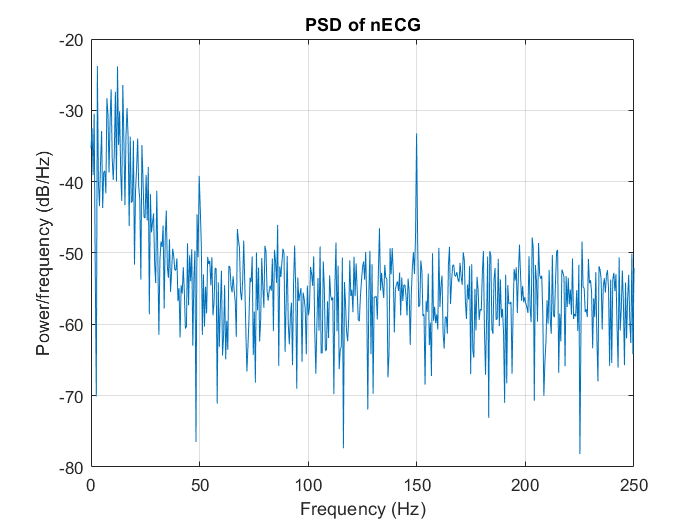


nfft = 1024;
window = rectwin(length(nECG));

figure;
periodogram(nECG,window,nfft,fs);
title('PSD of nECG');

% Designing the highpass and lowpass Kaiser windows

% Highpass filter
highpass_w_p = 1.5;
highpass_w_s = 0.5;

% Lowpass filter
lowpass_w_p = 70; 
lowpass_w_s = 90; 

delta = 0.01;

fs = 500;

% Calculate the required filter order and beta for Kaiser window
[highpass_M, highpass_wc, highpass_beta, highpass_filter_type] = kaiserord([highpass_w_s highpass_w_p], [0 1], [delta delta], fs);
[lowpass_M, lowpass_wc, lowpass_beta, lowpass_filter_type] = kaiserord([lowpass_w_p lowpass_w_s], [1 0], [delta delta], fs);
fprintf('For High pass filter M = %d, Beta = %d ',highpass_M, highpass_beta)

For High pass filter M = 1118, Beta = 3.395321e+00 

fprintf('For Low pass filter M = %d and Beta = %d ',lowpass_M, lowpass_beta)

For Low pass filter M = 56 and Beta = 3.395321e+00 


% Create the filters using fir1 with Kaiser window
highpass_b = fir1(highpass_M, highpass_wc, highpass_filter_type, kaiser(highpass_M+1, highpass_beta)); % numerator coeff. (High Pass)
lowpass_b = fir1(lowpass_M, lowpass_wc, lowpass_filter_type, kaiser(lowpass_M+1, lowpass_beta)); % numerator coeff. (Low Pass)
highpass_a = 1; % denominator coeff. (High Pass)
lowpass_a = 1;% denominator coeff. (Low Pas)

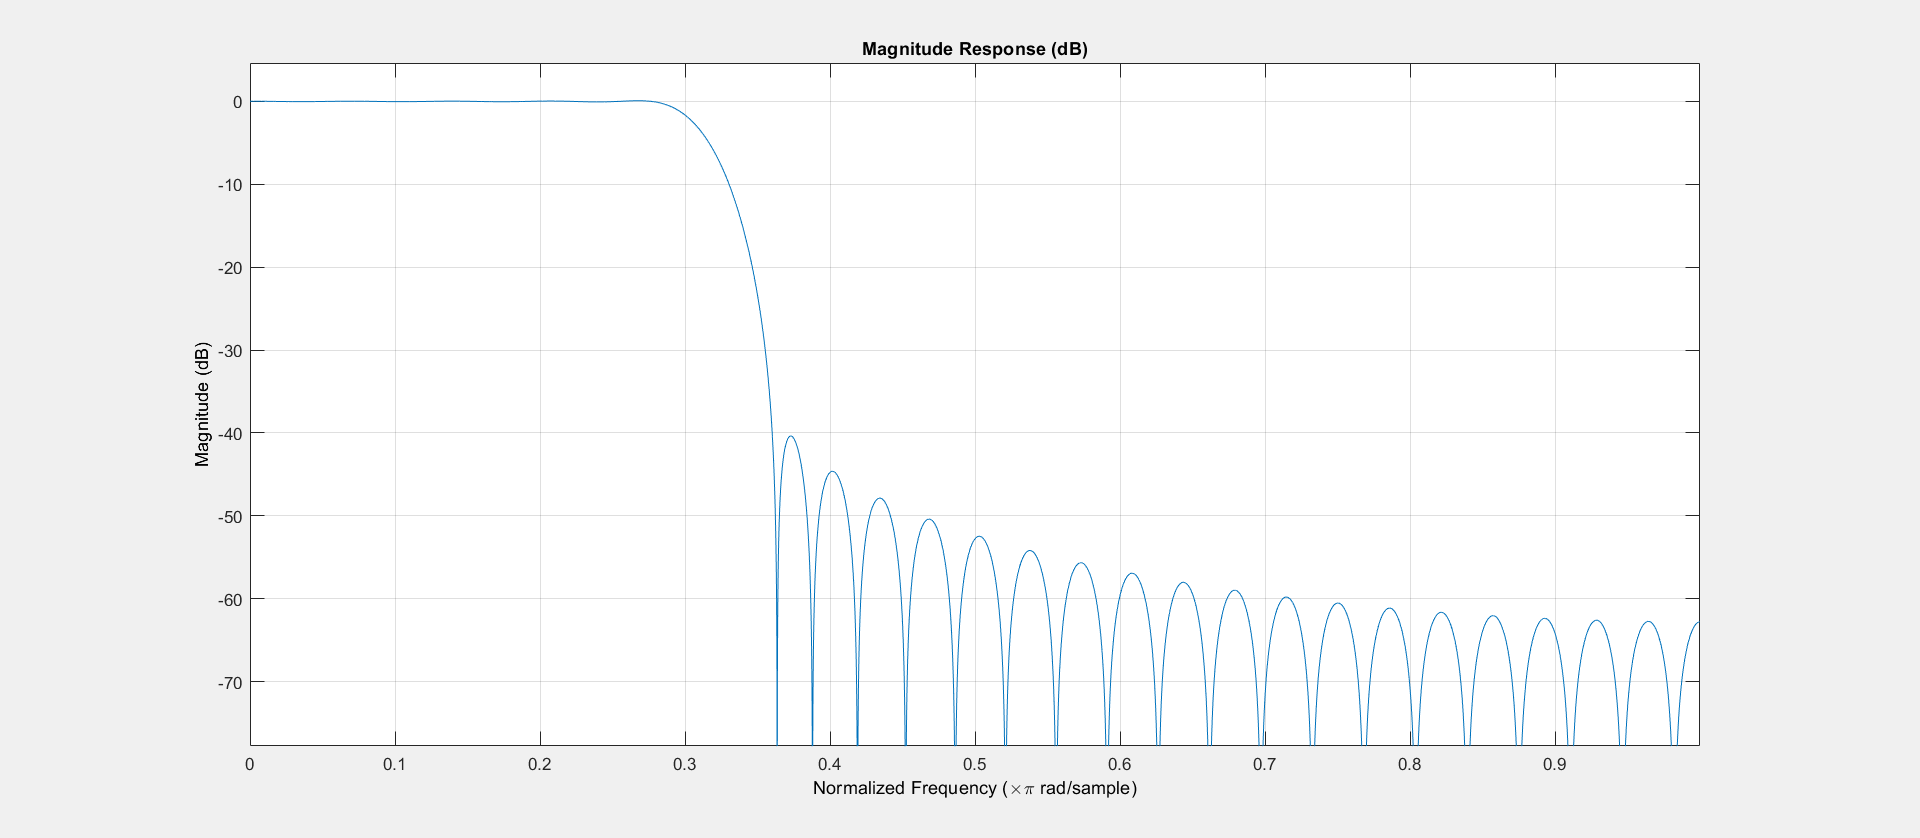

fvtool(lowpass_b, lowpass_a);

%fvtool(highpass_b, highpass_a);

% Designing the Comb Filter

% Cutoff Frequencies
fstop_1 = 50;
fstop_2 = 100;
fstop_3 = 150;

% Specify zeros in the complex z-plane
zeros_locations = [exp(1i*(2*pi*fstop_1/fs)), exp(-1i*(2*pi*fstop_1/fs)), ...
    exp(1i*(2*pi*fstop_2/fs)), exp(-1i*(2*pi*fstop_2/fs)), ...
    exp(1i*(2*pi*fstop_3/fs)), exp(-1i*(2*pi*fstop_3/fs))];  

% Compute FIR Filter Coefficients
% Convert to (b_0 + b_1*z^-1 +  b_2*z^-2 ...) format
combfilt_b = poly(zeros_locations);

% Set the gain equals to 1 at oHz.
combfilt_b = combfilt_b/sum(combfilt_b);
combfilt_a = 1;



% Step by step cascading of FIR filters

comb_filtered_ = filter(combfilt_b,combfilt_a,nECG);
comb_filtered = [comb_filtered_(4:end),zeros(1,3)];

lowpass_filtered_nECG_ = filter(lowpass_b, lowpass_a, comb_filtered);
lowpass_filtered_nECG = [lowpass_filtered_nECG_(29:end),zeros(1,28)];

highpass_filtered_nECG_ = filter(highpass_b,highpass_a,lowpass_filtered_nECG);
highpass_filtered_nECG = [highpass_filtered_nECG_(560:end),zeros(1,559)];

cascaded_filtered_ECG_fir_step = highpass_filtered_nECG;

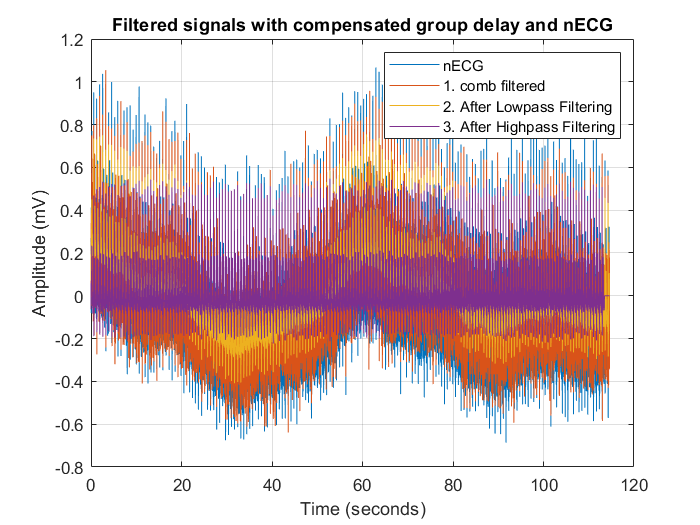

figure; 

plot(time, nECG); 
hold on;  

plot(time, comb_filtered); 
hold on;  

plot(time, lowpass_filtered_nECG); 
hold on;

plot(time, highpass_filtered_nECG); 
hold on;


title('Filtered signals with compensated group delay and nECG');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
legend('nECG','1. comb filtered', '2. After Lowpass Filtering', '3. After Highpass Filtering');  % Add legend to distinguish the plots

grid on;

% Create digital filter objects
highpass_filt_object = dfilt.df2(highpass_b, highpass_a);  % Filter 1
lowpass_filt_object = dfilt.df2(lowpass_b, lowpass_a);  % Filter 2
comb_filt_object = dfilt.df2(combfilt_b, combfilt_a);  % Filter 3

cascade_filter = dfilt.cascade(comb_filt_object, lowpass_filt_object, highpass_filt_object);
cascaded_filtered_ECG_ = filter(cascade_filter, nECG);
cascaded_filtered_ECG_fir = [cascaded_filtered_ECG_(591:end),zeros(1,590)];

save('cascaded_filtered_ECG_fir.mat', 'cascaded_filtered_ECG_fir');

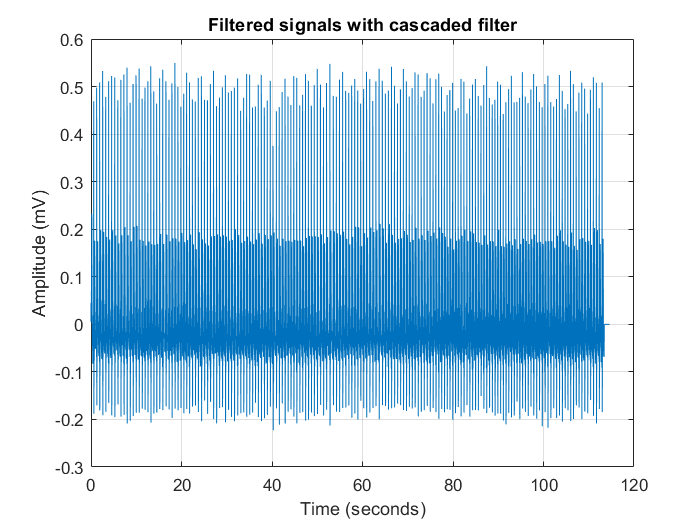

figure; % plot the cascaded filter effect

plot(time, cascaded_filtered_ECG_fir); 
title('Filtered signals with cascaded filter');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');

grid on;

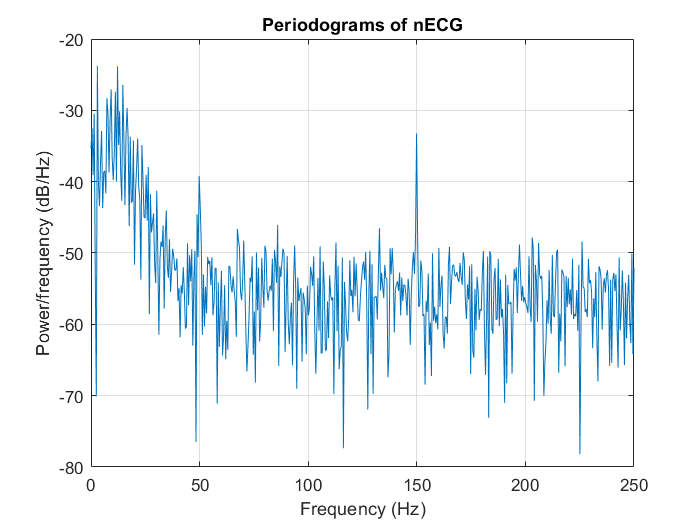

figure; % Plotting periodograms of filtered signals

periodogram(nECG,window,nfft,fs); 
title('Periodograms of nECG')
grid on;

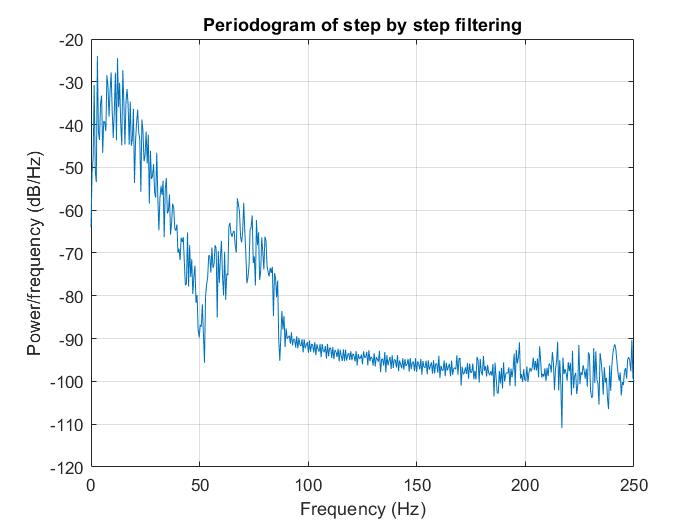


figure;
periodogram(cascaded_filtered_ECG_fir_step,window,nfft,fs); 
title('Periodogram of step by step filtering')
grid on;

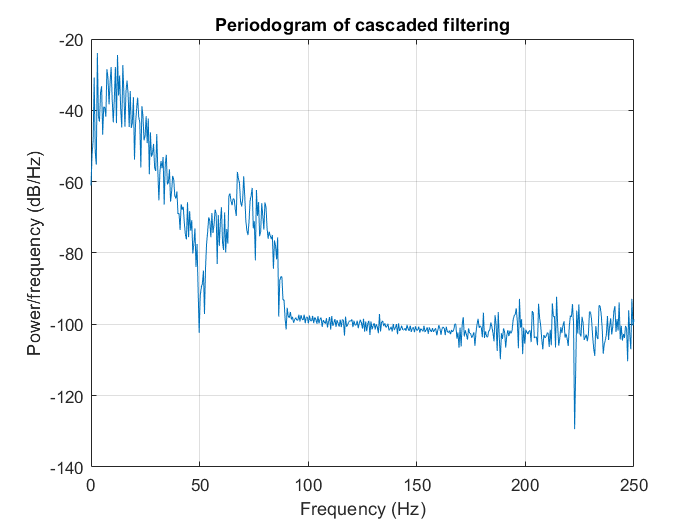


figure;
periodogram(cascaded_filtered_ECG_fir,window,nfft,fs); 
title('Periodogram of cascaded filtering')
grid on;

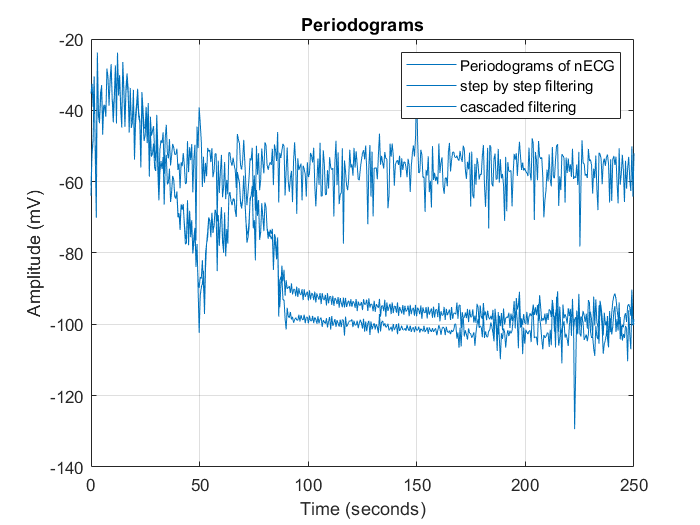

figure;

periodogram(nECG,window,nfft,fs); 
hold on;

periodogram(cascaded_filtered_ECG_fir_step,window,nfft,fs); 
hold on;

periodogram(cascaded_filtered_ECG_fir,window,nfft,fs); 
hold on;

legend('Periodograms of nECG', 'step by step filtering', 'cascaded filtering');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
title('Periodograms')
grid on;

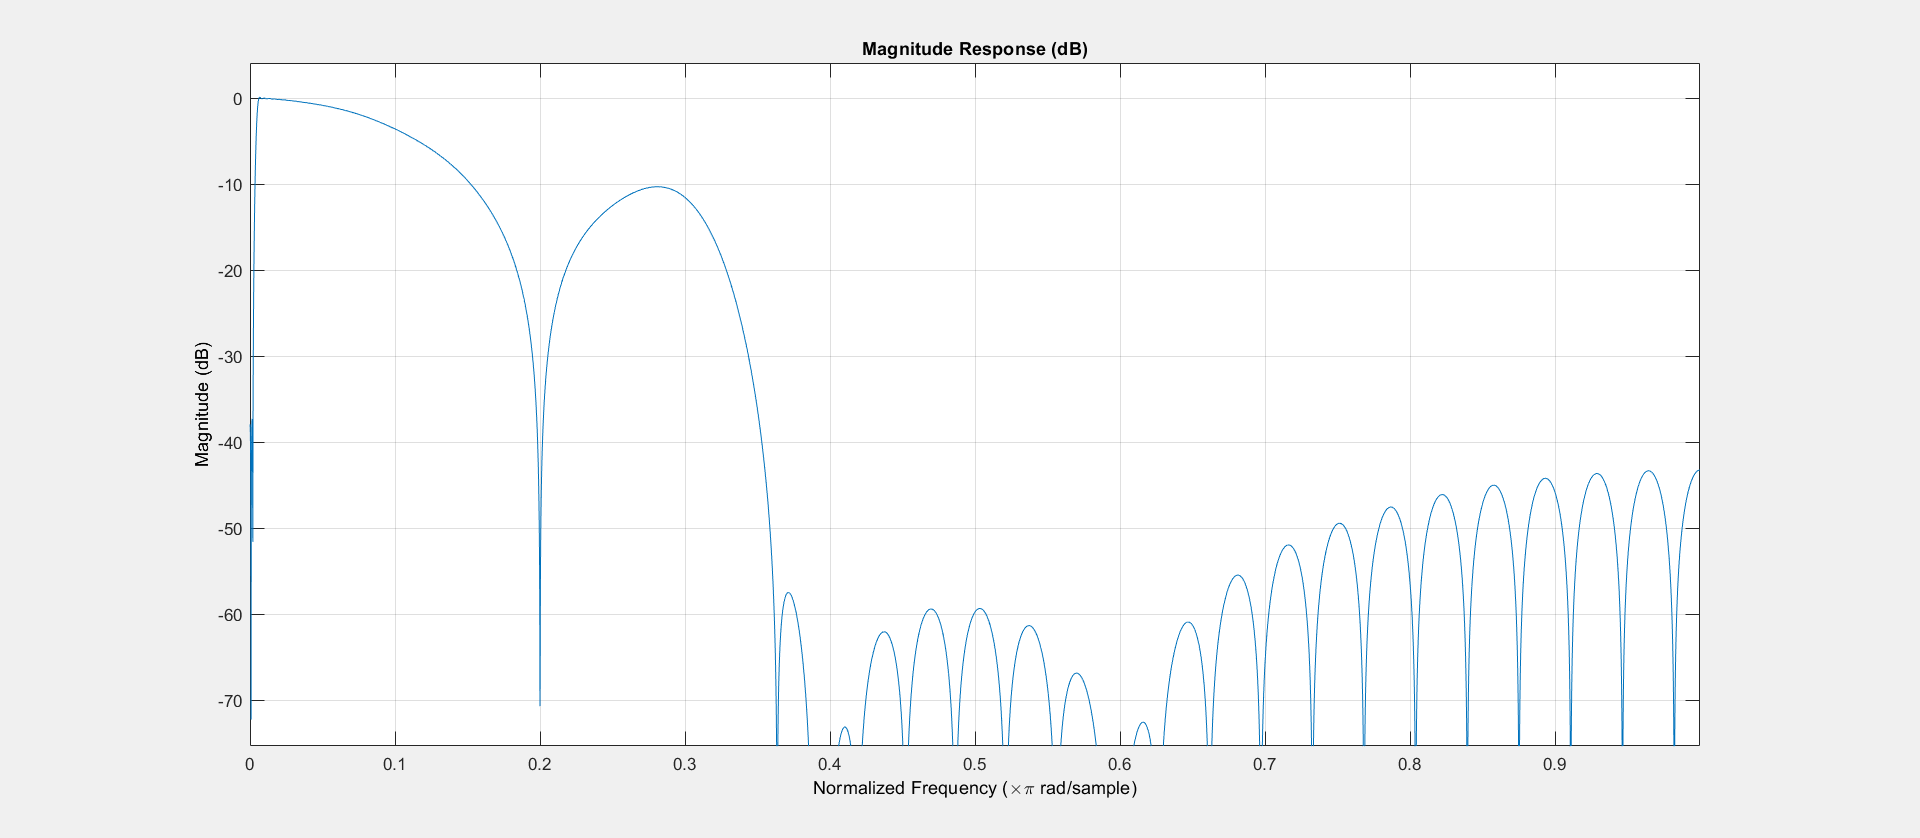

fvtool(cascade_filter);